# TOPSIS法

clc, clear
% 输入原始数据
a=[0.1	5	5000	4.7
 0.2	6	6000	5.6
 0.4	7	7000	6.7
 0.9	10	10000	2.3
 1.2	2	400	    1.8];
[m,n]=size(a);      % m是行数（方案数），n是列数（属性数）

#### 区间型属性的变换

`设第`j`个指标的最优属性区间为`$[a_j^0,a_j^\ast  ]$`，`$ a_j^\prime $`为无法容忍下限，`$ a_j^\prime \prime $`为无法容忍上限，则：`

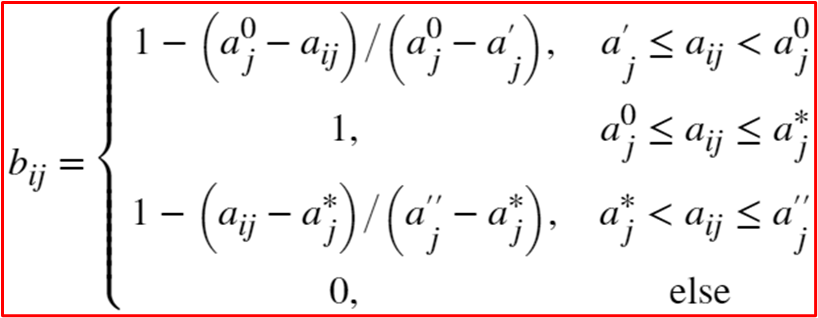

% 定义函数句柄b2，相当于在此定义了一个函数
% @(qujian,lb,ub,x)意味着调用b2时，需要给它括号里的四个参数
% (x>=lb & x<qujian(1))是逻辑与，如果&符号左右两边的条件都满足，则为1，否则为0
% 四种情况是互斥的，所以可以乘以各自区间条件逻辑计算后相加
a2=@(qujian,lb,ub,x)...
(1-(qujian(1)-x)./(qujian(1)-lb)).*(x>=lb & x<qujian(1))...
+(x>=qujian(1) & x<=qujian(2))...
+(1-(x-qujian(2))./(ub-qujian(2))).*(x>qujian(2) & x<=ub); 

% 设最优区间等参数
qujian=[5,6]; lb=2; ub=12;
a(:,2)=a2(qujian,lb,ub,a(:,2));     % 对生师比进行变换

#### 向量规范化

每一列（同一属性/指标）的元素值都化为0到1的值，且平方和为1

norm求向量数范，等于一个向量中的所有元素求平方和再开根

公式：$b_{i j}=\frac{a_{i j}}{\sqrt{\sum_{i=1}^{m} a_{i j}^{2}}}$

for j=1:n
    b(:,j)=a(:,j)/norm(a(:,j));  %向量规划化
end

#### 加权后求解

w=[0.2 0.3 0.4 0.1];  
ww = repmat(w,m,1);     % repmat复制得到m个权重矩阵w，在矩阵下面排列
c=b.*ww;      %求加权后的矩阵；

% 注意正理想解和负理想解的定义
% max(c)是包含矩阵c每一列的最大值的行向量
Cstar=max(c);    %求正理想解
Cstar(4)=min(c(:,4))  %属性4为成本型的！！！专门修改它

Cstar =     0.1530    0.1791    0.2759    0.0174


C0=min(c);       %q求负理想解
C0(4)=max(c(:,4))        %属性4为成本型的！！！专门修改它

C0 =     0.0128         0    0.0110    0.0648



for i=1:m
    Sstar(i)=norm(c(i,:)-Cstar);  %求到正理想解的距离
    S0(i)=norm(c(i,:)-C0);      %求到负理想的距离
end

% 综合评价指数f
f=S0./(Sstar+S0);
[sf,ind]=sort(f,'descend')       % 'descend'表示降序排序，得分高的放在第一位

sf =     0.7003    0.6255    0.5787    0.5258    0.3165


ind =      4     3     2     1     5


sf是对综合评价指数f降序排序后的结果，ind对应原始元素的序号

ind=[4 3 2 1 5]，代表第一名是第4号院校，第2名是3号院校……

% 本文件出自b站/公众号：数学建模BOOM
% 关注微信公众号：数学建模BOOM，回复"课程"
% 查看全套视频课程+配套PPT课件+代码文件